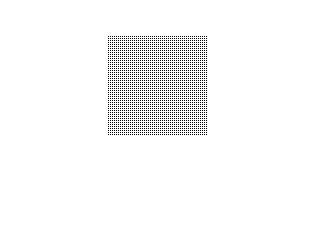

interval = 2;

x = linspace(1,100);
y = linspace(1,100);
[X,Y] = meshgrid(x,y);

image = (mod(X, interval) == 0 | mod(Y, interval) == 0);

figure
imshow(image, [])

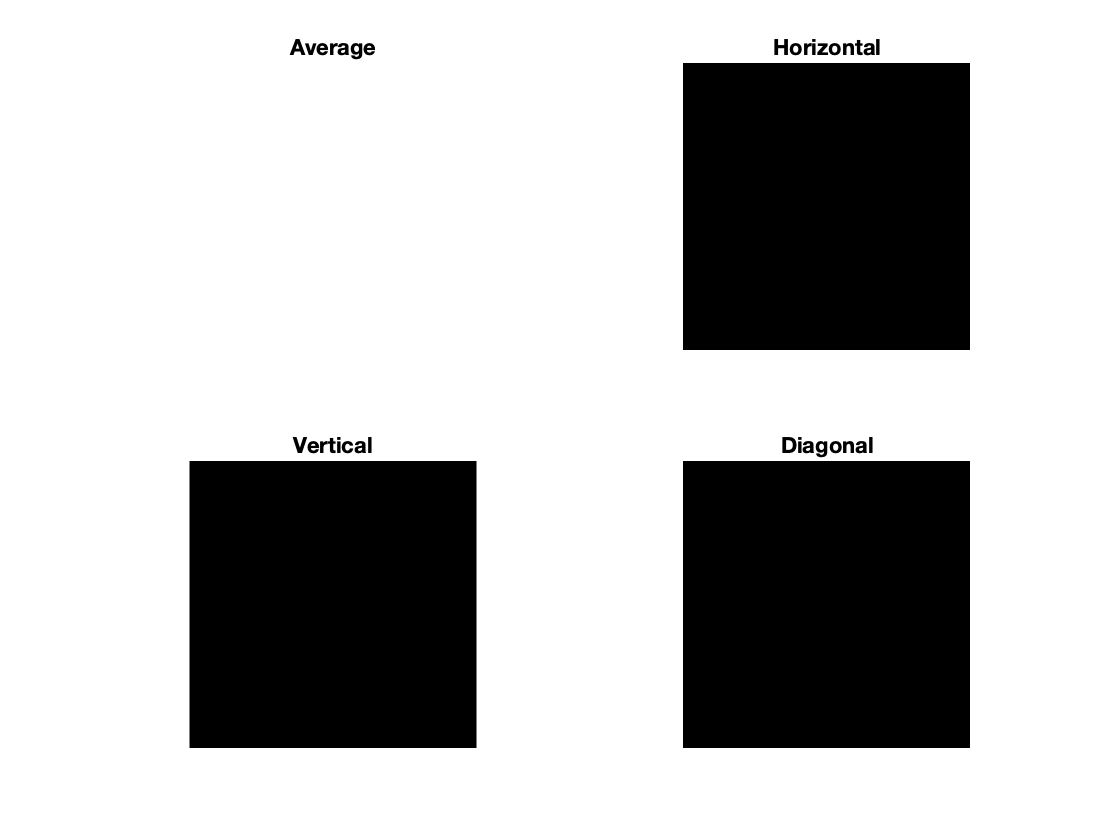


[cA, cH, cV, cD] = dwt2(image, 'haar');
figure
subplot(2,2,1)
imshow(cA, [])
title('Average')

subplot(2,2,2)
imshow(cH, [])
title('Horizontal')

subplot(2,2,3)
imshow(cV, [])
title('Vertical')

subplot(2,2,4)
imshow(cD, [])
title('Diagonal')

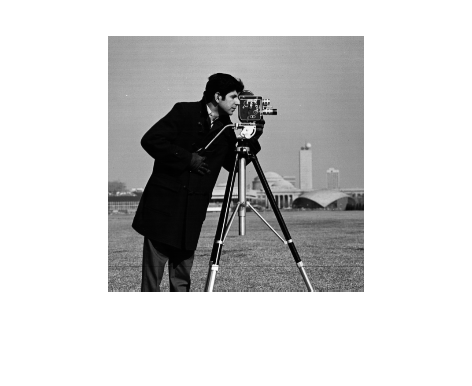

cameraman = imread('Important_files/cameraman.tif');
figure
imshow(cameraman, [])

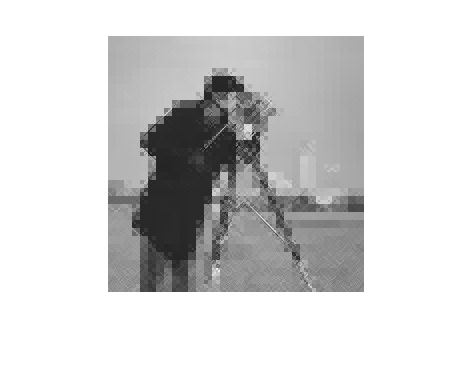


[cA1, cH1, cV1, cD1] = dwt2(cameraman, 'haar');
[cA2, cH2, cV2, cD2] = dwt2(cA1, 'haar');
[cA3, cH3, cV3, cD3] = dwt2(cA2, 'haar');

recon_2 = idwt2(cA3, [], [], cD3, 'haar');
recon_1 = idwt2(recon_2, [], [], cD2, 'haar');
recon = idwt2(recon_1, [], [], cD1, 'haar');

figure
imshow(recon, [])